# Compile Figures for Synthetic Data

%%%%%%
%Script for compiling the figure generator
%%%%%%

clear all
close all



%What is the name of the site?
names = "Upper Kuparuk River";

%What is the original data?
originaldata = {'UK_data.txt'};


%do you want the figure saved?
printfig  = true;

%Where do you want to save figures?
workdirfigures = '~/Documents/GitHub/Permafrost_ERRA/datERRA/UK_months';
%What is your project name?
ProjFolder = '/figures/';

%Where is your data?
workdir = workdirfigures;




%Set directories
workdirfig_ = {workdirfigures, ProjFolder};
workdirfig=char(strcat(workdirfig_(1),workdirfig_(2)));
if ~exist(workdirfig, 'dir')
    cd(workdirfigures)
    mkdir(ProjFolder)
end
cd(workdir)

Get the Temperatures for the range

opts = delimitedTextImportOptions("NumVariables", 12);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["shortt", "shortt_1", "short_t_cont_num", "years", "months", "RH", "airtemp", "dewpoint", "snowdepth", "groundwater", "P", "Q","ThawDepth"];
opts.VariableTypes = ["datetime", "datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double","double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "shortt", "InputFormat", "yyyy-MM-dd HH:mm");
opts = setvaropts(opts, "shortt_1", "InputFormat", "yyyy-MM-dd HH:mm");

% Import the data
UKsynthesizeddata = readtable("/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/archive/UK_ThawingDepth_daily/UK_synthesized_data.txt", opts);

ThawDepth = table2array(UKsynthesizeddata(:,"ThawDepth"));
Q = table2array(UKsynthesizeddata(:,"Q"));
P = table2array(UKsynthesizeddata(:,"P"));
Temp = table2array(UKsynthesizeddata(:,"airtemp"));
months = table2array(UKsynthesizeddata(:,"months"));
shortt = table2array(UKsynthesizeddata(:,"shortt"));
%% Clear temporary variables
clear opts


%Lets look at how many data points in each bracket
monthbrakes = {'TillJune','June2July','July2August','August'};

brakets_(:,1) = months<6 & Q > 0 & P > 0 & Temp>=2;
brakets_(:,2)= months==6 & Q > 0 & P > 0 & Temp>=2;
brakets_(:,3) = months==7 & Q > 0 & P > 0 &Temp>=2;
brakets_(:,4) = months >= 8 & Q > 0 & P > 0 & Temp>=2;

NO_TillJune = sum(brakets_(:,1));
NO_June2July = sum(brakets_(:,2));
NO_July2August = sum(brakets_(:,3));
NO_August = sum(brakets_(:,4));


Lets plot the results

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%FIGURES%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
colors = [179,0,0
227,74,51
252,141,89
253,204,138
254,240,217]./255;



% prepare formating options
HA = {'HorizontalAlignment','left','center','right'};
VA = {'VerticalAlignment','bottom','middle','top'};
UN = {'Units','Normalized','Inches'};
TX = {'Interpreter','Latex'};
TL = {'TickLabelInterpreter','Latex'};
LW = {'LineWidth',1,1.25,1.5,2*2};
FS = {'FontSize',10,15,18,21,24*2};
MS = {'MarkerSize',6,8,12};
LS = {'LineStyle','-','--','-.',':'};
% LC = {'Color',color};
LL = {'Location','northwest','northeast','southwest','southeast'};



%Plotting profiles
axh = 5;
axw = 1.5*axh;
ahs = 0.15;
avs = 0.15;
axb = 0.7;
axt = 0.5;
axl = 1.0;
axr = 0.5;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + 1*axh + 1*avs + 1*ht + axt ;
fw = axl  + axw + ahs + cbw + axr;


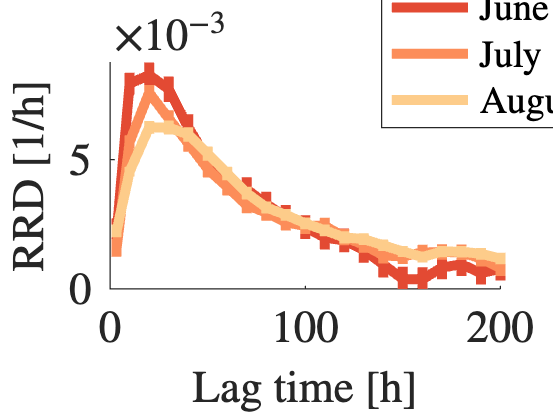

%set figure page
f1 = figure;
 % set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
 % set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
 % set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
 % set(f1,'Resize','off','Toolbar','none');
 % ax = axes('Units','Inches','position',[axl axb axw axh]);

maxRRD = zeros(size(monthbrakes));
maxRRDlgt = zeros(size(monthbrakes));

for jj = 2:numel(monthbrakes) 
str = {'1hr_simple_',monthbrakes{jj},'_RRD.txt'};
filename=char(strcat(str(1),str(2),str(3)));
[maxRRD(jj),maxRRDlgt(jj),RRD(:,jj),se(:,jj),lagt(:,jj)] = figtRRD_plot_TempBrackets(filename,workdir,colors(jj,:));
end




% line(ax.XLim, [0, 0], 'Color', 'black', 'LineStyle', '--', 'LineWidth', 1.5);
set(gca,'XLim',[min(min(lagt)),max(max(lagt))],'Ylim',[0, max(max([RRD+se]))],TL{:},FS{[1,4]});

%set axis
xlabel('Lag time [h]',TX{:},FS{[1,4]},UN{[1,3]});
ylabel('RRD [1/h]',TX{:},FS{[1,4]},UN{[1,3]});
     
% legend("TillJune","June2July","July2August","GreaterAugust",FS{[1,3]},TX{[1,2]});
[lgd, hobj, ~, ~] = legend("June","July","August",FS{[1,3]},TX{[1,2]},LL{[1,3]});
adjustLegendSize(lgd,hobj,1.05,1.00,10,1);
  
% ttl2 = sprintf('Number of valid points = %d', NO_June2July + NO_July2August + NO_August);
    % title({names,ttl2},TX{:},FS{[1,4]},UN{[1,3]},'Position',[axw/2+ahs/2,axh])

% msg = sprintf('Number of valid input values \n are %d, %d, %d and %d respectively', NO_TillJune, NO_June2July, NO_July2August, NO_GreaterAugust);
msg = sprintf('Number of valid input values \n are  %d, %d and %d respectively',NO_June2July, NO_July2August, NO_August);
dim = [.5 .015 .2 .2];
% annotation('textbox', dim, 'String', msg, 'FitBoxToText','on',FS{[1,3]},TX{[1,2]});
%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'ltRRD_months' };
  format    = '-dpng';
  resl      = '-r400';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end

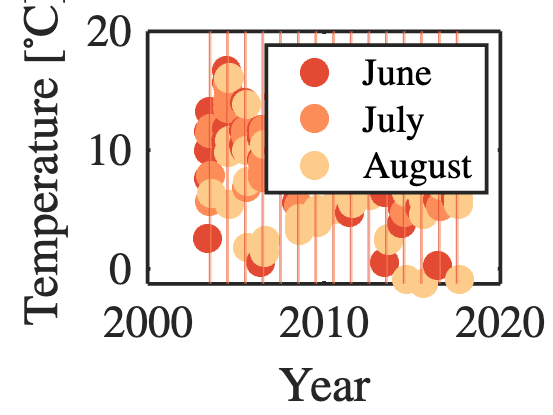

temp = importdata("/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/archive/UK_ThawingDepth_daily/airtemperature.mat");
airtemp = temp.airtemp;
time = temp.short_t_cont_num;
years = unique(floor(time));
for l = 1:numel(years)
June(l) = decyear([years(l),06,01]);
July(l) = decyear([years(l),07,01]);
August(l) = decyear([years(l),08,01]);
September(l) = decyear([years(l),09,01]);
end

% Define the number of hours in a week
            hours_per_week = 168;

        % Reshape the data into a matrix with one week per column
            num_weeks = floor(length(time)/hours_per_week);
            time_matrix = reshape(time(1:num_weeks*hours_per_week), hours_per_week, num_weeks);
            airtemp_matrix = reshape(airtemp(1:num_weeks*hours_per_week), hours_per_week, num_weeks);
           
        % Calculate the mean of each column to get the weekly averages
            time_w = nanmean(time_matrix, 1);
            airtemp_w = nanmean(airtemp_matrix, 1);

figure
for l = 1:numel(years)
    indx = time_w>=June(l) & time_w<July(l);
    plot(time_w(indx),airtemp_w(indx),'.','MarkerSize',35,'Color',colors(2,:))
    hold on
    indx = time_w>=July(l) & time_w<August(l);
    plot(time_w(indx),airtemp_w(indx),'.','MarkerSize',35,'Color',colors(3,:))
    indx = time_w>=August(l) & time_w<September(l);
    plot(time_w(indx),airtemp_w(indx),'.','MarkerSize',35,'Color',colors(4,:))
end
%             xline(June,'Color',colors(1,:))
            xline(July,'Color',colors(2,:))
            xline(August,'Color',colors(3,:))

xlabel('Year',TX{:},FS{[1,4]},UN{[1,3]});
ylabel('Temperature [$^{\circ}$C]',TX{:},FS{[1,4]},UN{[1,3]});
legend('June','July','August',FS{[1,3]},TX{[1,2]},LL{[1,3]})
set(gca, LW{[1,4]}, TL{:},FS{[1,4]});

temp = importdata("/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/archive/UK_ThawingDepth_daily/airtemperature.mat");
airtemp = temp.airtemp;
time = temp.short_t_cont_num;
years = unique(floor(time));
for l = 1:numel(years)
June(l) = decyear([years(l),06,01]);
July(l) = decyear([years(l),07,01]);
August(l) = decyear([years(l),08,01]);
September(l) = decyear([years(l),09,01]);
end

% Define the number of hours in a week
            hours_per_week = 168;

        % Reshape the data into a matrix with one week per column
            num_weeks = floor(length(time)/hours_per_week);
            time_matrix = reshape(time(1:num_weeks*hours_per_week), hours_per_week, num_weeks);
            airtemp_matrix = reshape(airtemp(1:num_weeks*hours_per_week), hours_per_week, num_weeks);
           
        % Calculate the mean of each column to get the weekly averages
            time_w = nanmean(time_matrix, 1);
            airtemp_w = nanmean(airtemp_matrix, 1);


Junedata =[];
Julydata = [];
Augustdata = [];
for l = 1:numel(years)
    indx = time_w>=June(l) & time_w<July(l);
    Junedata = [Junedata airtemp_w(indx)];

    indx = time_w>=July(l) & time_w<August(l);
        Julydata = [Julydata airtemp_w(indx)];

    indx = time_w>=August(l) & time_w<September(l);
    Augustdata = [Augustdata airtemp_w(indx)];
end
fig1 = figure

fig1 =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 278 560 420]
       Units: 'pixels'

  Show all properties


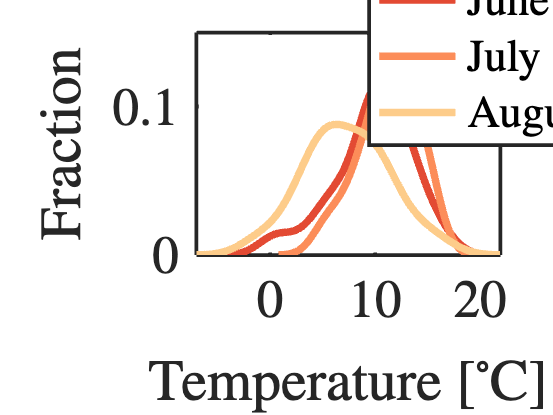

[f,xi] = ksdensity(Junedata);
plot(xi,f,'Color',colors(2,:),'LineWidth',3)
hold on
[f,xi] = ksdensity(Julydata);
plot(xi,f,'Color',colors(3,:),'LineWidth',3)
[f,xi] = ksdensity(Augustdata);
plot(xi,f,'Color',colors(4,:),'LineWidth',3)


ylabel('Fraction',TX{:},FS{[1,5]},UN{[1,3]});
xlabel('Temperature [$^{\circ}$C]',TX{:},FS{[1,5]},UN{[1,3]});
[lgd, hobj, ~, ~] = legend('June','July','August',FS{[1,4]},TX{[1,2]},LL{[1,3]});
adjustLegendSize(lgd,hobj,1.05,1.00,10,1);

set(gca, LW{[1,4]}, TL{:},FS{[1,5]});

if printfig
  cd(workdirfig);
  % set printing options
  str       = {'TempMonths' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(fig1,format,resl,rend,figname,'-loose');
end

%%%Precipitation by month
time = shortt;


Junedata = P(month(time)==6);
Julydata = P(month(time)==7);
Augustdata = P(month(time)==8);

Junedata(Junedata == 0) = [];
Julydata(Julydata == 0) = [];
Augustdata(Augustdata == 0) = [];
fig1 = figure

fig1 =   Figure (23) with properties:

      Number: 23
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 278 560 420]
       Units: 'pixels'

  Show all properties


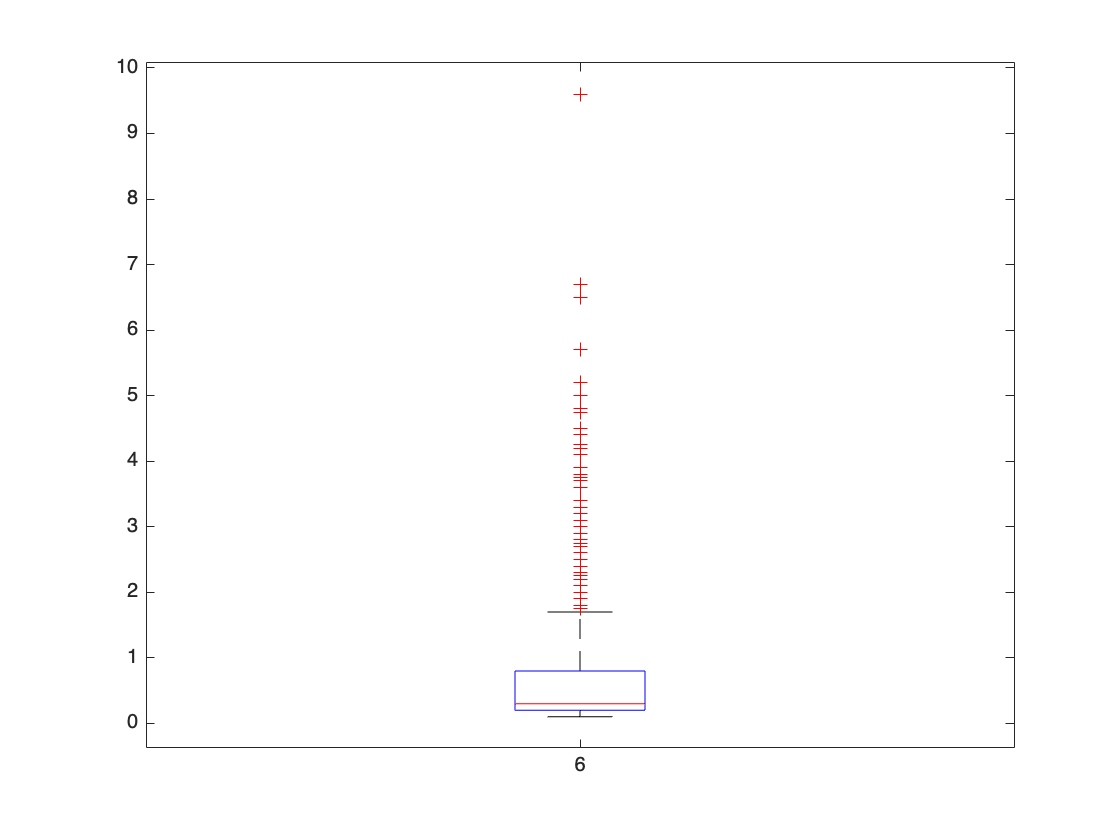




% Create box plot for June data
h1 = boxplot(Junedata, 'Positions', [1], 'Labels', {'6'});

hold on

% Create box plot for July data
h2 = boxplot(Julydata, 'Positions', [2], 'Labels', {'7'});
hold on

% Create box plot for August data
h3 = boxplot(Augustdata, 'Positions', [3], 'Labels', {'8'});
 hold off


% % Set axis labels
xlabel('Month',TX{:},FS{[1,5]},UN{[1,3]});
ylabel('Precipitation [mm/h]',TX{:},FS{[1,5]},UN{[1,3]});


% Set x-tick positions and labels
xticks([1, 2, 3])
xticklabels({'6', '7', '8'})

sJune = round(nansum(Junedata)./15);
sJuly = round(nansum(Julydata)./15);
sAugust = round(nansum(Augustdata)./15);

% Add labels to the box plots
text(1, max(Junedata)+1, ['', num2str(sJune), 'mm/mo'], 'HorizontalAlignment', 'center',TX{:},FS{[1,5]})
text(2, max(Julydata)+1, ['', num2str(sJuly), 'mm/mo'], 'HorizontalAlignment', 'center',TX{:},FS{[1,5]})
text(3, max(Augustdata)-4, ['', num2str(sAugust), 'mm/mo'], 'HorizontalAlignment', 'center',TX{:},FS{[1,5]})
set(gca, LW{[1,4]}, TL{:},FS{[1,5]});


if printfig
  cd(workdirfig);
  % set printing options
  str       = {'PrecipJJA' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(fig1,format,resl,rend,figname,'-loose');
end

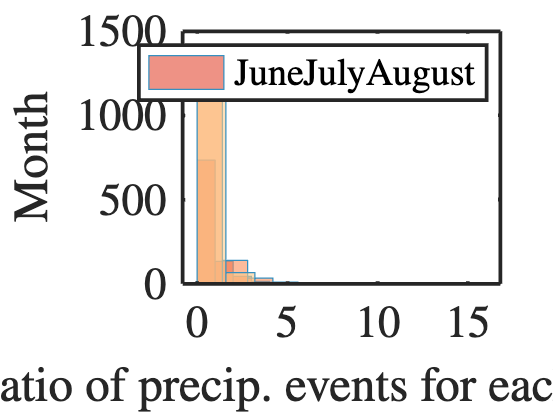


figure
histogram(Junedata,10,'EdgeColor',[54,144,192]./255,'FaceColor',colors(2,:))
hold on
histogram(Julydata,10,'EdgeColor',[54,144,192]./255,'FaceColor',colors(3,:))
histogram(Augustdata,10,'EdgeColor',[54,144,192]./255,'FaceColor',colors(4,:))



ylabel('Month',TX{:},FS{[1,4]},UN{[1,3]});
xlabel('Ratio of precip. events for each month',TX{:},FS{[1,4]},UN{[1,3]});
legend(['June','July','August'],FS{[1,3]},TX{[1,2]},LL{[1,3]});
set(gca, LW{[1,4]}, TL{:},FS{[1,4]});


%Precipitation at each month in each airtemp bracket
Junedata0l = P(month(time)==6&airtemp<0);
Julydata0l = P(month(time)==7&airtemp<0);
Augustdata0l = P(month(time)==8&airtemp<0);
Junedata02 = P(month(time)==6&airtemp>0&airtemp<2);
Julydata02 = P(month(time)==7&airtemp>0&airtemp<2);
Augustdata02 = P(month(time)==8&airtemp>0&airtemp<2);
Junedata2p = P(month(time)==6&airtemp>=2);
Julydata2p = P(month(time)==7&airtemp>=2);
Augustdata2p = P(month(time)==8&airtemp>=2);

%If precipitation of a certain type is 0, then remove the event
Junedata0l(Junedata0l == 0) = [];
Junedata02(Junedata02 == 0) = [];
Junedata2p(Junedata2p == 0) = [];
Julydata0l(Julydata0l == 0) = [];
Julydata02(Julydata02 == 0) = [];
Julydata2p(Julydata2p == 0) = [];
Augustdata0l(Augustdata0l == 0) = [];
Augustdata02(Augustdata02 == 0) = [];
Augustdata2p(Augustdata2p == 0) = [];

%Count all events and remove nan events for each  month
NOeventsJ = numel(Junedata0l) + numel(Junedata02) + numel(Junedata2p)...
    - sum(isnan(Junedata0l)) - sum(isnan(Junedata02))- sum(isnan(Junedata2p));

NOeventsJJ = numel(Julydata0l) + numel(Julydata02) + numel(Julydata2p)...
    - sum(isnan(Julydata0l))- sum(isnan(Julydata02))- sum(isnan(Julydata2p));

NOeventsA = numel(Augustdata0l) + numel(Augustdata02) + numel(Augustdata2p)...
    - sum(isnan(Augustdata0l))- sum(isnan(Augustdata02))- sum(isnan(Augustdata2p));

%Fraction of events for each month a certain type
NOJunedat(1) = (numel(Junedata0l) - sum(isnan(Junedata0l)))./NOeventsJ;
NOJunedat(2) = (numel(Junedata02) - sum(isnan(Junedata02)))./NOeventsJ;
NOJunedat(3) = (numel(Junedata2p) - sum(isnan(Junedata2p)))./NOeventsJ;
NOJulydat(1) = (numel(Julydata0l) - sum(isnan(Julydata0l)))./NOeventsJJ;
NOJulydat(2) = (numel(Julydata02) - sum(isnan(Julydata02)))./NOeventsJJ;
NOJulydat(3) = (numel(Julydata2p) - sum(isnan(Julydata2p)))./NOeventsJJ;
NOAugustdat(1) = (numel(Augustdata0l) - sum(isnan(Augustdata0l)))./NOeventsA;
NOAugustdat(2) = (numel(Augustdata02) - sum(isnan(Augustdata02)))./NOeventsA;
NOAugustdat(3) = (numel(Augustdata2p) - sum(isnan(Augustdata2p)))./NOeventsA;


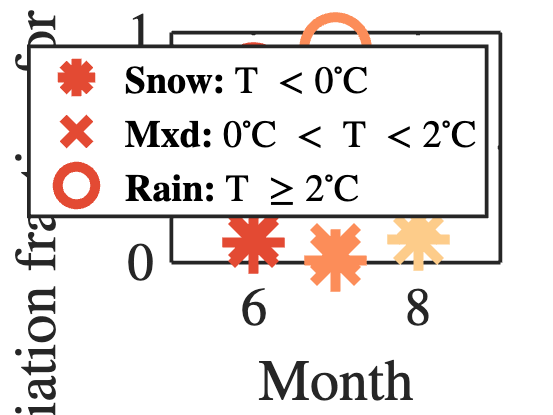


fig1 = figure;
mm = [6,7,8];
NOmonthsdat = [NOJunedat; NOJulydat; NOAugustdat];
sym = {'*','x','o'};
for l = 1:3 %month
    for ll = 1:3 %temp
   plot(mm(l), NOmonthsdat(l,ll),sym{ll},'Color',colors(l+1,:),'MarkerSize',25,'LineWidth',4)
   hold on
    end
end

ylabel('Precipiation fraction for each month',TX{:},FS{[1,5]},UN{[1,3]});
xlabel('Month',TX{:},FS{[1,5]},UN{[1,3]});
legend({'\textbf{Snow: } T $< 0^{\circ}$C','\textbf{Mxd: } $0^{\circ}$C $<$ T $< 2^{\circ}$C','\textbf{Rain: } T $\ge 2^{\circ}$C'},FS{[1,3]},TX{[1,2]},LL{[1,3]});
set(gca, LW{[1,4]}, 'XLim',[5,9],'Ylim',[0, 1],TL{:},FS{[1,5]});


if printfig
  cd(workdirfig);
  % set printing options
  str       = {'PrecipSMR_frac' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(fig1,format,resl,rend,figname,'-loose');
end

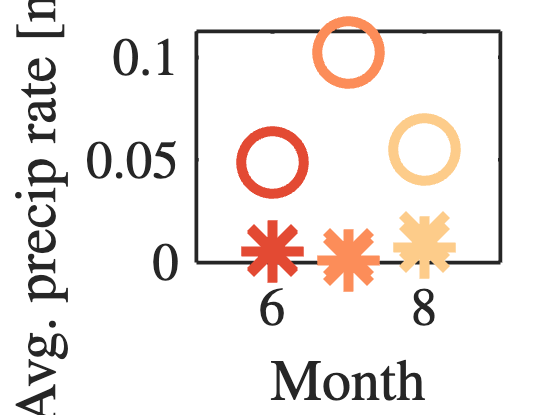


Junedata0l = P(month(time)==6&airtemp<0);
Julydata0l = P(month(time)==7&airtemp<0);
Augustdata0l = P(month(time)==8&airtemp<0);
Junedata02 = P(month(time)==6&airtemp>0&airtemp<2);
Julydata02 = P(month(time)==7&airtemp>0&airtemp<2);
Augustdata02 = P(month(time)==8&airtemp>0&airtemp<2);
Junedata2p = P(month(time)==6&airtemp>=2);
Julydata2p = P(month(time)==7&airtemp>=2);
Augustdata2p = P(month(time)==8&airtemp>=2);


NOeventsJ = numel(Junedata0l) + numel(Junedata02) + numel(Junedata2p)...
    - sum(isnan(Junedata0l)) - sum(isnan(Junedata02))- sum(isnan(Junedata2p));

NOeventsJJ = numel(Julydata0l) + numel(Julydata02) + numel(Julydata2p)...
    - sum(isnan(Julydata0l))- sum(isnan(Julydata02))- sum(isnan(Julydata2p));

NOeventsA = numel(Augustdata0l) + numel(Augustdata02) + numel(Augustdata2p)...
    - sum(isnan(Augustdata0l))- sum(isnan(Augustdata02))- sum(isnan(Augustdata2p));

%intensity of each precipitation type for each month.
NOJunedat(1) = (nansum(Junedata0l) )./NOeventsJ;
NOJunedat(2) = (nansum(Junedata02) )./NOeventsJ;
NOJunedat(3) = (nansum(Junedata2p) )./NOeventsJ;
NOJulydat(1) = (nansum(Julydata0l) )./NOeventsJJ;
NOJulydat(2) = (nansum(Julydata02) )./NOeventsJJ;
NOJulydat(3) = (nansum(Julydata2p) )./NOeventsJJ;
NOAugustdat(1) = (nansum(Augustdata0l) )./NOeventsA;
NOAugustdat(2) = (nansum(Augustdata02) )./NOeventsA;
NOAugustdat(3) = (nansum(Augustdata2p) )./NOeventsA;

fig1 = figure;
mm = [6,7,8];
NOmonthsdat = [NOJunedat; NOJulydat; NOAugustdat];
sym = {'*','x','o'};
for l = 1:3 %month
    for ll = 1:3 %temp
   plot(mm(l), NOmonthsdat(l,ll),sym{ll},'Color',colors(l+1,:),'MarkerSize',25,'LineWidth',4)
   hold on
    end
end

ylabel('Avg. precip rate [mm/h]',TX{:},FS{[1,5]},UN{[1,3]});
xlabel('Month',TX{:},FS{[1,5]},UN{[1,3]});
% legend({'\textbf{Snow: } T $< 0^{\circ}$C','\textbf{Mxd: } $0^{\circ}$C $<$ T $< 2^{\circ}$C','\textbf{Rain: } T $\ge 2^{\circ}$C'},FS{[1,3]},TX{[1,2]},LL{[1,3]});
set(gca,LW{[1,4]}, 'XLim',[5,9],'Ylim',[0, max(max(NOmonthsdat))*1.1],TL{:},FS{[1,5]});

if printfig
  cd(workdirfig);
  % set printing options
  str       = {'PrecipSMR_mmhr' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(fig1,format,resl,rend,figname,'-loose');
end

% 
% [f,xi] = ksdensity(Junedata0l);
% plot(xi,f,'-','Color',colors(2,:),'LineWidth',3)
% hold on
% [f,xi] = ksdensity(Junedata04);
% plot(xi,f,'--','Color',colors(2,:),'LineWidth',3)
% [f,xi] = ksdensity(Junedata4p);
% plot(xi,f,'-.','Color',colors(2,:),'LineWidth',3)
% 
% 
% figure
% [f,xi] = ksdensity(Julydata0l);
% plot(xi,f,'-','Color',colors(3,:),'LineWidth',3)
% hold on
% [f,xi] = ksdensity(Julydata04);
% plot(xi,f,'--','Color',colors(3,:),'LineWidth',3)
% [f,xi] = ksdensity(Julydata4p);
% plot(xi,f,'-.','Color',colors(3,:),'LineWidth',3)
% 
% figure
% [f,xi] = ksdensity(Augustdata0l);
% plot(xi,f,'-','Color',colors(4,:),'LineWidth',3)
% hold on
% [f,xi] = ksdensity(Augustdata04);
% plot(xi,f,'--','Color',colors(4,:),'LineWidth',3)
% [f,xi] = ksdensity(Augustdata4p);
% plot(xi,f,'-.','Color',colors(4,:),'LineWidth',3)
% legend('T \lt 0','0\lt T \lt 4', 'T \ge 4')


% Lets look at how ALT scaling goes with maxRRD
load('/Users/cansu/Documents/Polybox_ETH/Permafrost/Upper Kuparuk River Basin Alaska_river/data/soil data/ThawModel.mat')
monthAvgALT = monthAvg;
catchmentA = 1.42e14;%142 km^2 --> mm^2
volpotential = (monthAvgALT(8)-monthAvgALT(6))*catchmentA;
percpotential = volpotential/(catchmentA.*monthAvg(6));
RRDdec = maxRRD(end)-maxRRD(2);
percRRDdec = RRDdec./maxRRD(2);
D_RRD = maxRRD(2:end).*monthAvg(6:8);

%Calculate the monthly discharge to precipitation ratio
precip = importdata("/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/archive/UK_ThawingDepth_daily/precipitation.mat");
Precip = precip.P;
days = precip.short_t_cont_num;
Pyears = precip.years;
Pmonths = precip.months;
temp = importdata("/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/archive/UK_ThawingDepth_daily/airtemperature.mat");
airtemp = temp.airtemp;
discharge = importdata("/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/archive/UK_ThawingDepth_daily/discharge.mat");
Q = discharge.Q;
Q2P = Q./Precip;
P_Q = (Precip(Precip>0)-Q(Precip>0))./Precip(Precip>0);
monthAvg = zeros(1, 12);
for m = 1:numel(monthAvg)
    idx = Pmonths == m;
    idxP = idx(Precip>0);
    Q2PAvg(m) = nanmean(Q2P(idx)); 
    P_QAvg(m) = nanmean(P_Q(idxP));
end